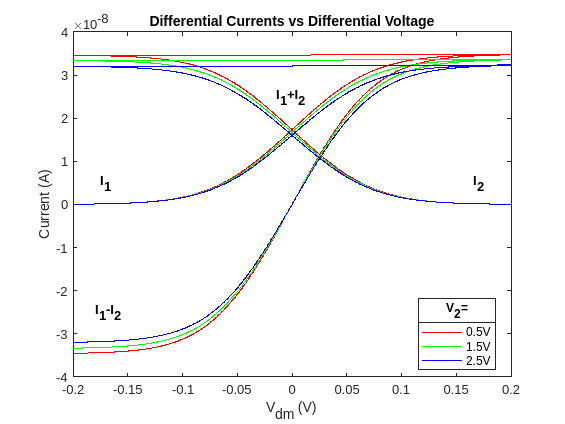

clf;
clear;

Vdm = linspace(-0.2,0.2,1001);

loadspice("05.txt");
I1_05 = V1;
I2_05 = V3;
Vn_05 = n001;
Isum_05 = I1_05 + I2_05;
Iminus_05 = I1_05 - I2_05;
% plot(Vdm,I1_05);
% hold on;
% plot(Vdm,I2_05);
% hold on;
% plot(Vdm,Iminus_05);
% hold on;linspace(-0.2,0.2,1001)
% plot(Vdm,Isum_05);


loadspice("15.txt");
I1_15 = V1;
I2_15 = V3;
Vn_15 = n001;
Isum_15 = I1_15 + I2_15;
Iminus_15 = I1_15 - I2_15;
% plot(Vdm,I1_15);
% hold on;
% plot(Vdm,I2_15);
% hold on;
% plot(Vdm,Iminus_15);
% hold on;
% plot(Vdm,Isum_15);

loadspice("25.txt");
I1_25 = V1;
I2_25 = V3;
Vn_25 = n001;
Isum_25 = I1_25 + I2_25;
Iminus_25 = I1_25 - I2_25;
% hold on;
% plot(Vdm,Iminus_25);
% hold on;
% plot(Vdm,Isum_25);
% 
% plot(Vdm,I1_25);
% hold on;
% plot(Vdm,I2_25);


figure()
p1 = plot(Vdm, I1_05, "r-"); hold on
plot(Vdm, I2_05, "r-");
plot(Vdm, Isum_05, "r-");
plot(Vdm, Iminus_05, "r-");

p2 = plot(Vdm, I1_15, "g-");
plot(Vdm, I2_15, "g-");
plot(Vdm, Isum_15, "g-");
plot(Vdm, Iminus_15, "g-");

p3 = plot(Vdm, I1_25, "b-");
plot(Vdm, I2_25, "b-");
plot(Vdm, Isum_25, "b-");
plot(Vdm, Iminus_25, "b-");
hold off
xlabel("V_{dm} (V)")
ylabel("Current (A)")
lgd=legend([p1 p2 p3], {'0.5V', '1.5V', '2.5V'}, Location="best");
title("Differential Currents vs Differential Voltage")
title(lgd, 'V_2=')

text_x1 = -0.180;
text_y1 = -0.25e-7;
text_x2 = -0.175;
text_y2 = 0.05e-7;
text_x3 = 0.165;
text_y3 = 0.05e-7;
text_x4 = -0.015;
text_y4 = 0.25e-7;

text(text_x1, text_y1, 'I_{1}-I_{2}', 'FontSize', 10,'FontWeight','bold', 'Color', 'k');
text(text_x2, text_y2, 'I_{1}', 'FontSize', 10,'FontWeight','bold', 'Color', 'k');
text(text_x3, text_y3, 'I_{2}', 'FontSize', 10,'FontWeight','bold', 'Color', 'k');
text(text_x4, text_y4, 'I_{1}+I_{2}', 'FontSize', 10,'FontWeight','bold', 'Color', 'k');

Diff curren

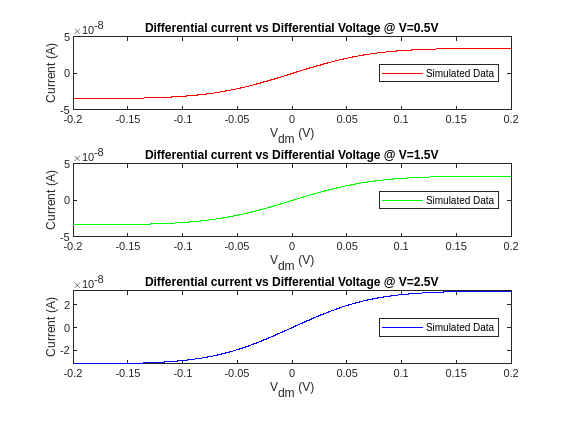


figure();


subplot(3, 1, 1); 
plot(Vdm, Iminus_05, "r-", 'DisplayName', 'Simulated Data');
title("Differential current vs Differential Voltage @ V=0.5V");
xlabel("V_{dm} (V)");
ylabel("Current (A)");
legend('Location', 'best');

% Subplot 2 for V=3.5
subplot(3, 1, 2); % 3 rows, 1 column, 2nd plot
plot(Vdm, Iminus_15, "g-", 'DisplayName', 'Simulated Data');
title("Differential current vs Differential Voltage @ V=1.5V");
xlabel("V_{dm} (V)");
ylabel("Current (A)");
legend('Location', 'best');

% Subplot 3 for V=4.5
subplot(3, 1, 3); % 3 rows, 1 column, 3rd plot
plot(Vdm, Iminus_25, "b-", 'DisplayName', 'Simulated Data');

title("Differential current vs Differential Voltage @ V=2.5V");
xlabel("V_{dm} (V)");
ylabel("Current (A)");
legend('Location', 'best');

Node Voltage

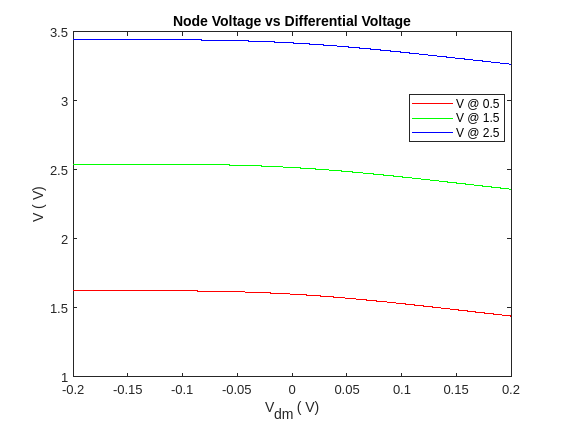

figure();
plot(Vdm,Vn_05,'r-', 'DisplayName',"V @ 0.5"); hold on; 
plot(Vdm,Vn_15,'g-', 'DisplayName',"V @ 1.5"); hold on;
plot(Vdm,Vn_25,'b-', 'DisplayName',"V @ 2.5");

legend('show', Location='best');
xlabel('V_{dm} ( V)');
ylabel('V ( V)');
title('Node Voltage vs Differential Voltage');

Strong Inversion @ 1.5 V , Vb  = 4.2V

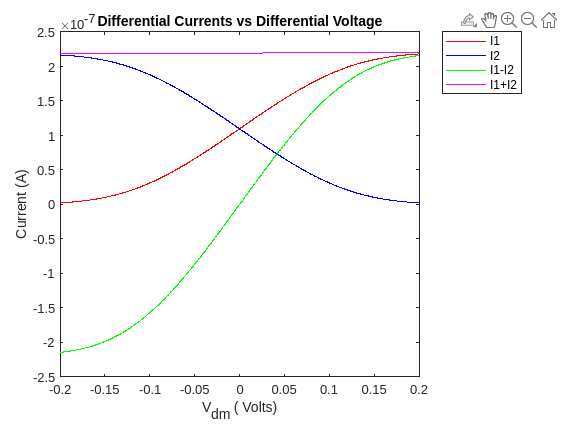

figure();

loadspice("strong15.txt");
I1_15strong = V1;
I2_15strong = V3;
Vn_15strong = n001;
Isum_15strong = I1_15strong + I2_15strong;
Iminus_15strong = I1_15strong - I2_15strong;
plot(Vdm,I1_15strong, 'r-','DisplayName',"I1" );
hold on;
plot(Vdm,I2_15strong, 'b-','DisplayName',"I2" );
hold on;
plot(Vdm,Iminus_15strong, 'g-','DisplayName',"I1-I2" );
hold on;
plot(Vdm,Isum_15strong,  'm-','DisplayName',"I1+I2" );

legend('show', Location='northeastoutside');
xlabel('V_{dm} ( Volts)');
ylabel('Current (A)');
title('Differential Currents vs Differential Voltage');

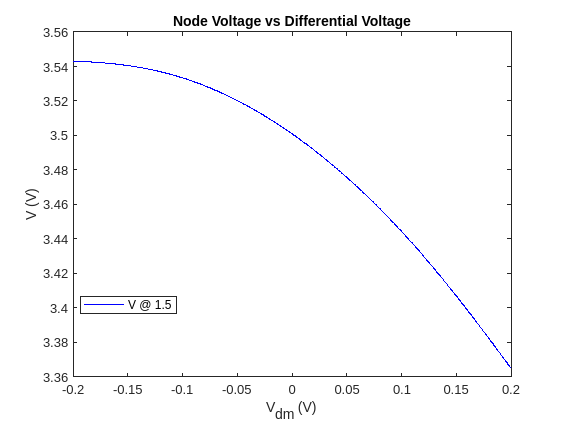

figure();
plot(Vdm,Vn_15strong,'b-','DisplayName',"V @ 1.5");

legend('show', Location='best');
xlabel('V_{dm} (V)');
ylabel('V (V)');
title('Node Voltage vs Differential Voltage');

In PMOS, the differential current is smaller, around 10^(-8), compared to NMOS which registers around 10^(-7). Additionally, the node voltage declines in PMOS but rises in NMOS. Even at strong inversion, the differential current remains lower in PMOS, and its node voltage decreases, contrasting with NMOS where the node voltage increases.